# Filtro de Kalman

En este ejemplo se muestra cómo implementar un filtro de Kalman, utilizando el objeto `kalman `(https://es.mathworks.com/help/control/ref/ss.kalman.html). Este objeto utiliza unas ecuaciones ligeramente diferentes a las que se han explicado en el estado del arte del trabajo, pero que expresan el problema de forma similar. Escogí explicarlo de la otra forma en la teoría porque me resultaba más sencillo de comprender, pero aquí deben manejarse las otras, que se comentarán para señalar la similitud.

Se implementará un filtro de Kalman no estacionario, en el que se permite que los parámetros del sistema varíen en el tiempo, es decir, las matrices y parámetros del sistema se actualizan dinámicamente en cada paso de tiempo para adaptarse a los cambios en el sistema y a las fuentes de ruido. 

El objetivo es detectar la propagación de un incendio en un entorno forestal.

## Filtro de Kalman no estacionario 

El filtro de Kalman no estacionario tiene como ecuaciones de actualización las que se muestran a continuación. En el filtro variante en el tiempo, tanto la matriz de covarianza de error `P(t)` como la ganancia de Kalman` K(t) (`o` Mx(t)` como se refieren en https://es.mathworks.com/help/control/ref/ss.kalman.html`)` pueden variar en el tiempo. El sistema queda modelado de la siguiente forma:

Actualización del estado:  


$$\[\begin{array}{l}
\hat x\left[ {n + 1|n} \right] = A\hat x\left[ {n|n} \right] + Bu\left[ n \right] + Bw\left[ n \right]\\
P\left[ {n + 1|n} \right] = AP\left[ {n|n} \right]{A^T} + BQ{B^T}
\end{array}\]$$


Actualización de la medición:  


$$\[\begin{array}{l}
\hat x\left[ {n|n} \right] = \hat x\left[ {n|n - 1} \right] + {M_x}\left[ n \right]\left( {y\left[ n \right] - C\hat x\left[ {n|n - 1} \right]} \right)\\
{M_x}\left[ n \right] = P\left[ {n|n - 1} \right]{C^T}{\left( {CP\left[ {n|n - 1} \right]{C^T} + R\left[ n \right]} \right)^{ - 1}}\\
P\left[ {n|n} \right] = \left( {I - {M_x}\left[ n \right]C} \right)P\left[ {n|n - 1} \right]\\
\hat y\left[ {n|n} \right] = C\hat x\left[ {n|n} \right]
\end{array}\]$$


Se observa que son las mismas ecuaciones que las que se han obtenido en la teoría, pero con esta notación `C = H, Mx = K `y la observación `z` ahora se representa con `y`. También, se divide el vector de errores `e `del estado del arte en `u` y `w`, vectores que introducen las variables externas que afectan al estado y al ruido, respectivamente. Ambos están influenciados por la matriz` B, `que también afecta a la incertidumbre en la predicción` Q.`

En el siguiente fragmento de código se está creando el modelo que se utilizará para diseñar el filtro de Kalman, con la función `ss` (State-Space) de MATLAB. La matriz A representa la dinámica del sistema, la matriz B representa la influencia de las entradas, la matriz C representa la relación entre el estado y la salida y la matriz D representa la influencia de las entradas en la salida.

También se agrega la covarianza de ruido del proceso Q, que representa la incertidumbre del estado del sistema, y la covarianza de ruido del sensor R, que representa la incertidumbre en las mediciones debido al ruido o errores en los sensores. 

El parámetro `Ts` se puede establecer en -1, lo que indica que el sistema es discreto y no tiene un tiempo de muestreo específico; o bien asignar un valor de modo que se establezca que el sistema es continuo y con el que se determina la frecuencia con la que se obtienen las muestras y se actualizan las estimaciones o predicciones. El tiempo de muestreo es una consideración importante, ya que afecta la precisión y la estabilidad del sistema. Un tiempo de muestreo demasiado largo puede causar una falta de precisión en las estimaciones o una respuesta lenta del sistema, mientras que un tiempo de muestreo demasiado corto puede introducir ruido en las mediciones. Se ha escogido `Ts = 1`.

La opción `'InputName',{'u' 'w'}` se utiliza para asignar nombres a las entradas del sistema, donde `'u'` representa la entrada principal y `'w'` representa el ruido del proceso. La opción `'OutputName','y'` se utiliza para asignar un nombre a la salida del sistema, que es la medición.

A = [1   0    1 
     0   1    0 
     0   1    0];

B = [1
     0
     1];

C = [1 0 0];

D = 0;

Q = 2; 
R = 1; 

Ts = 1;
sys = ss(A,[B B],C,D,Ts,'InputName',{'u' 'w'},'OutputName','y');  

En el contexto de la simulación del filtro de Kalman, `u` se utiliza como la señal de entrada conocida al sistema. En este caso, se utiliza la función seno, para tener una señal de entrada conocida y poder evaluar el desempeño del filtro de Kalman al estimar la verdadera salida del sistema. 

Ahora, se generan vectores de ruido de predicción y ruido de medición utilizando los valores de covarianza de ruido Q y R.

El vector de ruido de predicción, `w`, se genera utilizando la función `randn` para generar valores aleatorios distribuidos normalmente con media cero y desviación estándar igual a la raíz cuadrada de la covarianza de ruido del proceso `Q`. Su longitud es igual a la longitud del vector de tiempo `t, `que también se especifica. El vector de ruido de medición, `v`, se genera de manera similar utilizando `R`. 

De este modo, se puede simular las perturbaciones y errores asociados con el sistema y las mediciones, lo que permite evaluar el desempeño del filtro de Kalman en condiciones realistas.

t = (0:100)';
u = sin(t/5);

rng(10,'twister');               % semilla para reproducibilidad
w = sqrt(Q)*randn(length(t),1);
v = sqrt(R)*randn(length(t),1);

El comando `lsim(sys,[u w])` se utiliza para simular la respuesta de dicho modelo con la entrada `u` y el ruido `w`. `sys` es el modelo definido previamente. La salida es `yt`, que representa la respuesta verdadera simulada. A continuación, se agrega el ruido en las mediciones v a la respuesta verdadera simulada `yt` para obtener la respuesta con ruido `y`. La variable `y` representa la respuesta con ruido, que se utilizará como entrada para el filtro de Kalman.

yt = lsim(sys,[u w]);   
y = yt + v;         

Ahora, se implementa el filtro según el modelo explicado anteriormente.

P = B*Q*B';         % calcula la covarianza inicial del error
x = zeros(3,1);     % inicializa la estimación del estado del sistema

ye = zeros(length(t),1);       % este vector almacena las estimaciones de la medición
ycov = zeros(length(t),1);     % almacena las covarianzas de la medición estimada
errcov = zeros(length(t),1);   % almacena las covarianzas del error de estimación

for i=1:length(t)
  Mxn = P*C'/(C*P*C'+R);    % actualización de la matriz de la ganancia de Kalman
  x = x + Mxn*(y(i)-C*x);   % actualización de la estimación del estado con las mediciones
  P = (eye(3)-Mxn*C)*P;     % actualización de la matriz la covarianza P
                            % eye(3) = matriz identidad 3x3


  ye(i) = C*x;              % actualización de la medición, y = Hx en el estado del arte
  errcov(i) = C*P*C';       % covarianzas del error de estimación


  x = A*x + B*u(i);        % actualización del estado con la matriz de transición y la señal de entrada
  P = A*P*A' + B*Q*B';     % actualización de la matriz de covarianza utilizando la matriz de transición

end

En la primera gráfica se muestra la respuesta verdadera de la planta (azul) y la respuesta filtrada (roja). Estas líneas representan cómo evoluciona la salida del sistema a lo largo del tiempo. Al comparar las dos líneas, se puede observar cómo el filtro de Kalman se ajusta a la respuesta verdadera y proporciona una estimación suavizada de la salida del sistema. Es decir, permite evaluar la capacidad del filtro de Kalman para seguir la respuesta verdadera de la planta y cómo se ajusta a las variaciones en la señal.

En la segunda se representan los errores entre las mediciones y las estimaciones del filtro de Kalman. Si el filtro de Kalman está funcionando correctamente, se espera que las líneas estén cerca de cero o que tengan fluctuaciones pequeñas alrededor de cero.

Si los errores son pequeños y las respuestas filtradas siguen de cerca las respuestas verdaderas, indica que el filtro de Kalman está funcionando de manera efectiva y está proporcionando una buena estimación del estado del sistema.

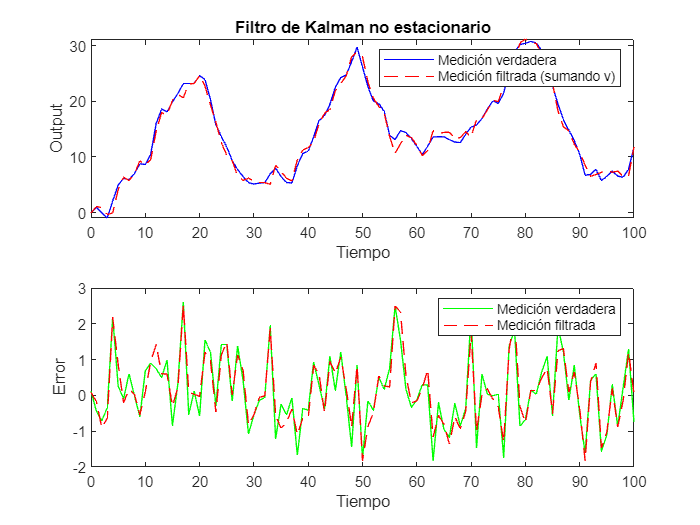

subplot(211), plot(t,yt,'b',t,ye,'r--')
xlabel('Tiempo'), ylabel('Output')
title('Filtro de Kalman no estacionario')
legend('Medición verdadera','Medición filtrada (sumando v)')
subplot(212), plot(t,yt-y,'g',t,yt-ye,'r--'),
xlabel('Tiempo'), ylabel('Error')
legend('Medición verdadera','Medición filtrada')

Al ejecutar el bucle principal del filtro de Kalman, se calcula y almacena la covarianza del error de estimación en cada iteración, en la variable `errcov`. Esta se puede trazar en función del tiempo, y la gráfica muestra cómo varía la precisión de la estimación del filtro. Si la covarianza del error tiende a un valor constante o converge a un valor de estado estacionario, esto indica que el filtro ha alcanzado un equilibrio y está proporcionando una estimación estable y confiable.

La representación de la covarianza del error a lo largo del tiempo te permite evaluar el rendimiento del filtro de Kalman y determinar si se ha estabilizado correctamente. Si la covarianza del error sigue cambiando significativamente incluso después de un largo período de tiempo, esto puede indicar que el filtro no ha convergido o que existen problemas en el modelo o en las estimaciones de ruido.

En este caso, la covarianza converge en pocos pasos de tiempo.

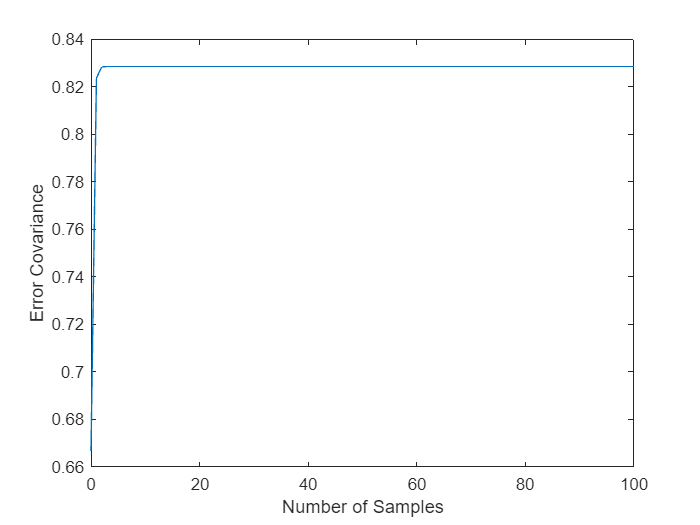

figure
plot(t,errcov) 
xlabel('Number of Samples'), ylabel('Error Covariance')

El filtro está pensado para reducir el error debido al ruido en las mediciones. Para confirmar esta reducción, se calcula la covarianza del error antes de filtrar (covarianza del error de mediciones) y tras filtrar (covarianza del error de estimación).

Si la covarianza del error de estimación (EstErrCov) es significativamente menor que la covarianza del error de las mediciones (MeasErrCov), esto indica que el filtro ha logrado reducir efectivamente el impacto del ruido en las mediciones y mejorar la precisión de la estimación.

% error entre la respuesta verdadera simulada (yt) y la respuesta con ruido (y)
MeasErr = yt - y;
MeasErrCov = sum(MeasErr.*MeasErr)/length(MeasErr) %  suma el producto del error con sí mismo (elemento a elemento) y luego divide por la longitud del error

MeasErrCov = 0.9871

% error entre la respuesta verdadera simulada (yt) y la respuesta estimada (ye)
EstErr = yt - ye;
EstErrCov = sum(EstErr.*EstErr)/length(EstErr)

EstErrCov = 0.8863

Cuando el filtro de Kalman alcanza el estado estacionario, significa que ha convergido a una configuración estable y sus valores internos ya no cambian con el tiempo. En este estado, los valores en la matriz de ganancia Mxn (utilizada en la actualización de la medición) son equivalentes a los valores calculados para el filtro de Kalman de estado estacionario, es decir, en el que no se modifican los parámetros en cada paso de tiempo, que se denotan como Mx.

La matriz de ganancia Mxn se calcula en cada paso de actualización de la medición para adaptarse a las condiciones del sistema y las mediciones. A medida que el filtro alcanza el estado estacionario, los valores en Mxn convergen a los valores que corresponderían a Mx, proporcionando la ganancia óptima.

Mxn

Mxn =     0.8284
         0
    0.3431


La gráfica generada a continuación muestra la relación entre la salida verdadera simulada (`yt`) y la salida estimada por el filtro de Kalman (`ye`). La línea azul representa la salida verdadera simulada y la línea roja representa la estimación del filtro de Kalman. Al trazar ambas líneas en la misma gráfica, podemos visualizar y comparar la coincidencia entre la salida verdadera y la salida estimada. Si el filtro de Kalman está funcionando correctamente y la estimación es precisa, se esperaría que la línea roja esté cerca de la línea azul. 

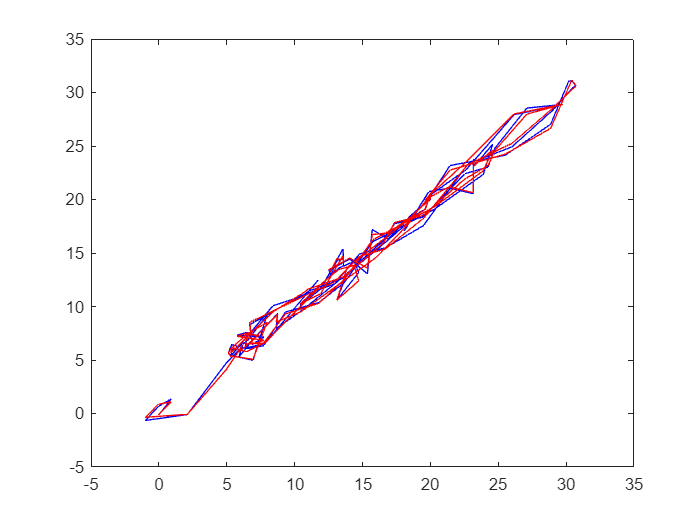

plot(yt,y,'b',yt,ye,'r')

Como me he inventado los datos (porque claramente un fuego no se propaga de la forma que he indicado), sale un movimiento un tanto extraño, pero se puede ver que la estimación parece ser buena.